% TTK4135 - Helicopter lab
% Hints/template for problem 2.
% Updated spring 2018, Andreas L. Flåten

## Initialization and model definition

init; % Change this to the init file corresponding to your helicopter

% State space model (continious time)
A = [0, 1, 0, 0;
     0, 0, -K_2, 0;
     0, 0, 0, 1;
     0, 0, -K_1 * K_pp, -K_1 * K_pd];

B = [0;
     0;
     0;
     K_1 * K_pp];

% Discrete time system model. x = [lambda r p p_dot]'
delta_t	= 0.25; % sampling time
q = 0.12;

A1 = eye(4) + delta_t * A;
B1 = B * delta_t;


% Number of states and inputs
mx = size(A1,2); % Number of states (number of columns in A)
mu = size(B1,2); % Number of inputs(number of columns in B)



% Initial values
x1_0 = pi;                              % Lambda
x2_0 = 0;                               % r
x3_0 = 0;                               % p
x4_0 = 0;                               % p_dot
x0 = [x1_0 x2_0 x3_0 x4_0]';           % Initial values

% Time horizon and initialization
N  = 100;                               % Time horizon for states
M  = N;                                 % Time horizon for inputs
z  = zeros(N*mx+M*mu,1);                % Initialize z for the whole horizon
z0 = z;                                 % Initial value for optimization

% Bounds
ul 	    = -30 / 360 * 2 * pi;                    % Lower bound on control
uu 	    = 30 / 360 * 2 * pi;                    % Upper bound on control

xl      = -Inf*ones(mx,1);              % Lower bound on states (no bound)
xu      = Inf*ones(mx,1);               % Upper bound on states (no bound)
xl(3)   = -30 / 360 * 2 * pi;                           % Lower bound on state x3
xu(3)   = 30 / 360 * 2 * pi;                           % Upper bound on state x3

% Generate constraints on measurements and inputs
[vlb,vub]       = gen_constraints(N, M, xl, xu, ul, uu); % hint: gen_constraints
% vlb(N*mx+M*mu)  = 0;                    % We want the last input to be zero
% vub(N*mx+M*mu)  = 0;                    % We want the last input to be zero

% Generate the matrix Q and the vector c (objecitve function weights in the QP problem) 
Q1 = zeros(mx,mx);
Q1(1,1) = 2;                            % Weight on state x1
Q1(2,2) = 0;                            % Weight on state x2
Q1(3,3) = 0;                            % Weight on state x3
Q1(4,4) = 0;                            % Weight on state x4
P1 = q;                                % Weight on input
Q = gen_q(Q1, P1, N, M);                                  % Generate Q, hint: gen_q
[height_Q, width_Q] = size(Q)

height_Q = 500

width_Q = 500

c = zeros(height_Q, 1);                                  % Generate c, this is the linear constant term in the QP

## Generate system matrixes for linear model

Aeq = gen_aeq(A1, B1, N, mx, mu);             % Generate A, hint: gen_aeq
[height, width] = size(Aeq);
beq = zeros(height, 1); % Generate b
beq(1:4, 1) = A1 * x0;

## Solve QP problem with linear model

tic
[z,lambda] = quadprog(Q, c, [], [], Aeq, beq, vlb, vub); % hint: quadprog. Type 'doc quadprog' for more info 


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


t1=toc;

% Calculate objective value
phi1 = 0.0;
PhiOut = zeros(N*mx+M*mu,1);
for i=1:N*mx+M*mu
  phi1=phi1+Q(i,i)*z(i)*z(i);
  PhiOut(i) = phi1;
end

## Extract control inputs and states

u  = [z(N*mx+1:N*mx+M*mu);z(N*mx+M*mu)]; % Control input from solution

x1 = [x0(1);z(1:mx:N*mx)];              % State x1 from solution
x2 = [x0(2);z(2:mx:N*mx)];              % State x2 from solution
x3 = [x0(3);z(3:mx:N*mx)];              % State x3 from solution
x4 = [x0(4);z(4:mx:N*mx)];              % State x4 from solution

num_variables = 5/delta_t;
zero_padding = zeros(num_variables,1);
unit_padding  = ones(num_variables,1);

u   = [zero_padding; u; zero_padding];
x1  = [pi*unit_padding; x1; zero_padding];
x2  = [zero_padding; x2; zero_padding];
x3  = [zero_padding; x3; zero_padding];
x4  = [zero_padding; x4; zero_padding];

time = (0:size(u, 1)-1) * delta_t

time =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


u_time = timeseries(u, time)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [141x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [141x1 double]
        DataInfo: 

## Plotting

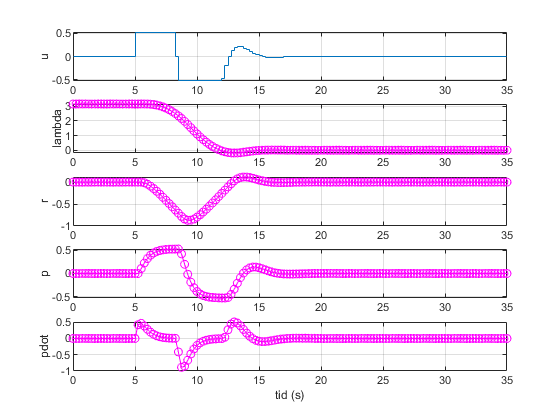

t = 0:delta_t:delta_t*(length(u)-1);

figure(2)
subplot(511)
stairs(t,u),grid
ylabel('u')
subplot(512)
plot(t,x1,'m',t,x1,'mo'),grid
ylabel('lambda')
subplot(513)
plot(t,x2,'m',t,x2','mo'),grid
ylabel('r')
subplot(514)
plot(t,x3,'m',t,x3,'mo'),grid
ylabel('p')
subplot(515)
plot(t,x4,'m',t,x4','mo'),grid
xlabel('tid (s)'),ylabel('pdot')